Colin Keenan

ECE 5470

2-10-2020

# Homework 2

1.  Gray Level Transformation - Write MATLAB code for power-law transformations $s={c*r}^{\gamma }$ and to apply the following images with coefficients:

## $\gamma =0\ldotp 4,c=1$applied to Fig2-1.jpg

clear

fprintf("Question 1, Part A, Section i:")

Question 1, Part A, Section i:

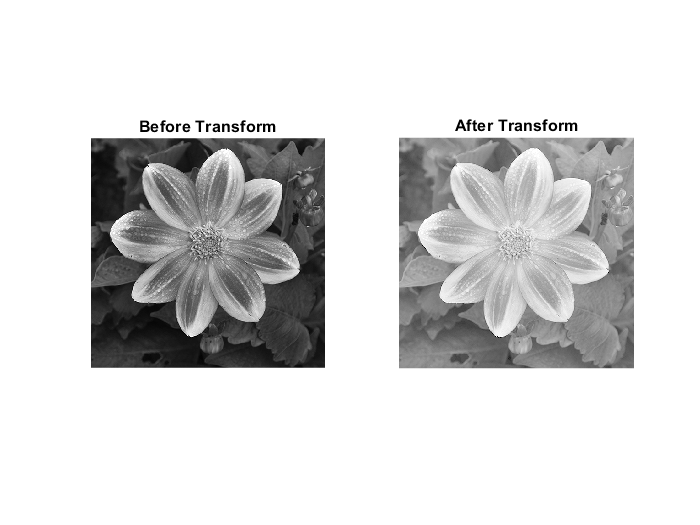


c = 1;      % c values from 0 to 10 with step size of 1
y = 0.4;    % gamma values from 0 to 25 with step size of 0.01

image = imread('Fig2-1.jpg');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        image_mod(i,j) = c * (image_double(i,j)^y);
    end
end

figure();
subplot(1,2,1)
imshow(image_double);
title("Before Transform");
subplot(1,2,2)
imshow(image_mod);
title("After Transform");

Explanation: Gamma transform with constants c = 1 and gamma = 0.4 were applied to the image. With these constants, the darks of the image are compressed down and the lights of the image are given more dynamic range, resulting in an overall brighter looking image, with the dark areas illimunated.

## $\gamma =0\ldotp 4,c=1$applied to Fig2-1.jpg

clear

fprintf("Question 1, Part A, Section ii:")

Question 1, Part A, Section ii:

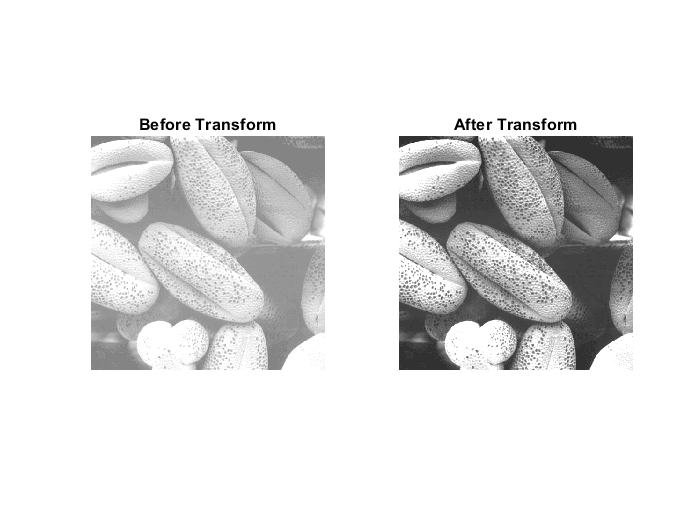


c = 1;      % c values from 0 to 10 with step size of 1
y = 2.5;    % gamma values from 0 to 25 with step size of 0.01

image = imread('Fig2-2.jpg');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        image_mod(i,j) = c * (image_double(i,j)^y);
    end
end

figure();
subplot(1,2,1)
imshow(image_double);
title("Before Transform");
subplot(1,2,2)
imshow(image_mod);
title("After Transform");

Explanation: Gamma transform with constants c = 1 and gamma = 2.5 were applied to the image. With these constants, the lights of the image are compressed down and the darks of the image are given more dynamic range, resulting in an overall darker looking image, with the overblown lighter areas darkened, revealing additional detail blown out prviously.

2.  Write MATLAB code for gray level slicing transformation and apply to Fig2-1.jpg

## Transform 1

clear

fprintf("Question 2, Transform 1")

Question 2, Transform 1

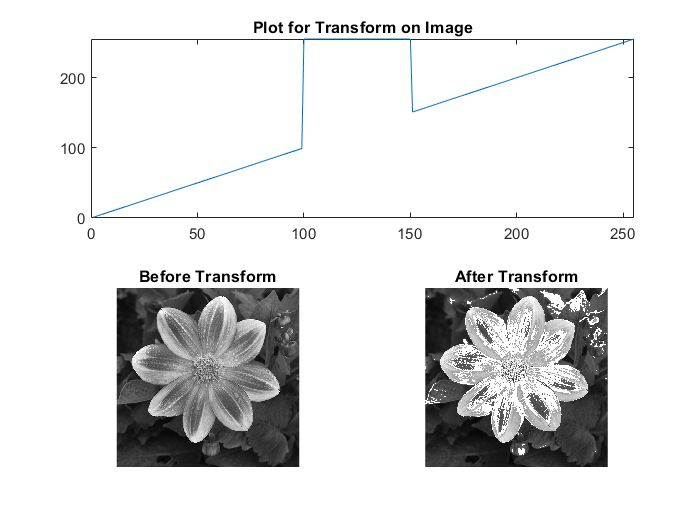

upper_range = 150/255;
lower_range = 100/255;

transform = 1:256;
for x = 1:256
    if((x >= lower_range*255) && (x <= upper_range*255))
        transform(x) = 255;
    else
        transform(x) = x;
    end
end

image = imread('Fig2-1.jpg');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_double(i,j);
        if((r >= lower_range) && (r <= upper_range))
            image_mod(i,j) = 1;
        else
            image_mod(i,j) = image_double(i,j);
        end
    end
end

figure();
subplot(2,2,[1 2])
plot(transform);
xlim([0,255]);
ylim([0,255]);
title("Plot for Transform on Image");
subplot(2,2,3)
imshow(image_double);
title("Before Transform");
subplot(2,2,4)
imshow(image_mod);
title("After Transform");

Explanation: Linear transform was applied except for the those values that ranged between 100 and 150 out of 255 intensity, which are set to the value of 255 or white. This results in the darks and lights of the image untouched, and the mids of the image, usually borders between light and dark to be highlighted, since they are given the value of 255.

## Transform 2

clear

fprintf("Question 2, Transform 2")

Question 2, Transform 2

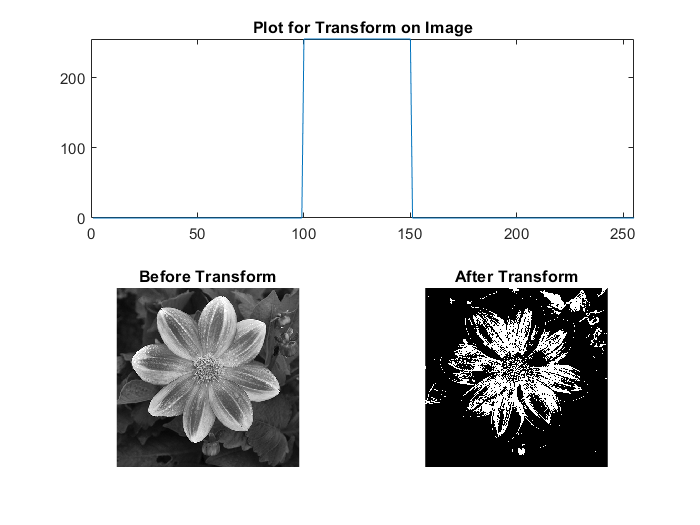

upper_range = 150/255;
lower_range = 100/255;

transform = 1:256;
for x = 1:256
    if((x >= lower_range*255) && (x <= upper_range*255))
        transform(x) = 255;
    else
        transform(x) = 0;
    end
end

image = imread('Fig2-1.jpg');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_double(i,j);
        if((r >= lower_range) && (r <= upper_range))
            image_mod(i,j) = 1;
        else
            image_mod(i,j) = 0;
        end
    end
end

figure();
subplot(2,2,[1 2])
plot(transform);
xlim([0,255]);
ylim([0,255]);
title("Plot for Transform on Image");
subplot(2,2,3)
imshow(image_double);
title("Before Transform");
subplot(2,2,4)
imshow(image_mod);
title("After Transform");

Explanation: Transform was applied to all values of the image, with those of intensities between 100 and 150 to be 255, or white, while the other values are set to 0, or black. This results non-standard 1-bit effect of the image with an adjustable range. The uses of this could be to highlight a certain feature of the image for futher image recognition or processing without the other parts of the image interfereing.

3.  Write MATLAB code for log transformations $s=c*\mathrm{log}\left(1+r\right)$ and apply to image Fig2_6.tif with coefficients below:

## c = 0.5

clear

fprintf("Question 3, Coefficient i:")

Question 3, Coefficient i:

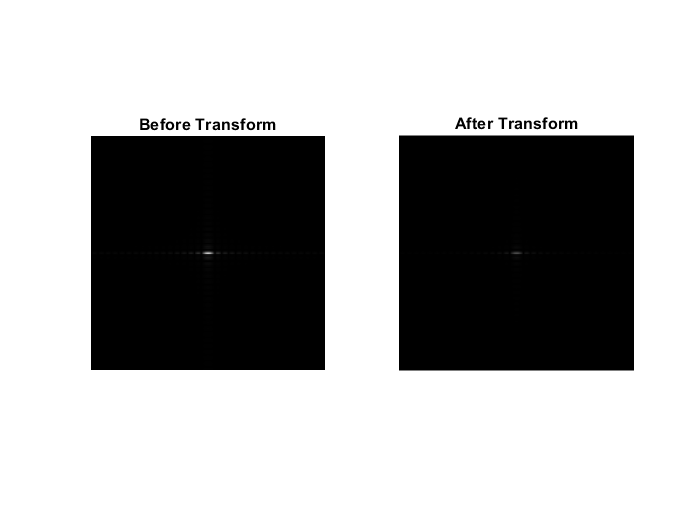


c = 0.5;    % c values from 0 to 100 with step size of 0.1

image = imread('Fig2_6.tif');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_double(i,j);
        image_mod(i,j) = c * (log(1+r));
    end
end

figure();
subplot(1,2,1)
imshow(image_double);
title("Before Transform");
subplot(1,2,2)
imshow(image_mod);
title("After Transform");

Explanation: Logarithmic transform applied to the image with the constant c = 0.5. This results in "dimming" the image and the difference between lights and darks according to the lograithmic scale. In this specific instance with this specific image, this does not have much purpose or use as the image already does not show a lot of detail in the lights, and is mostly dark.

## c = 1

clear

fprintf("Question 3, Coefficient ii:")

Question 3, Coefficient ii:

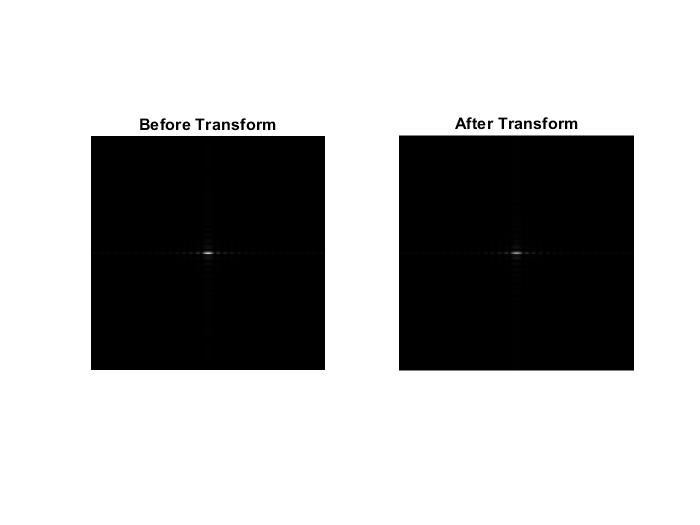


c = 1;    % c values from 0 to 100 with step size of 0.1

image = imread('Fig2_6.tif');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_double(i,j);
        image_mod(i,j) = c * (log(1+r));
    end
end

figure();
subplot(1,2,1)
imshow(image_double);
title("Before Transform");
subplot(1,2,2)
imshow(image_mod);
title("After Transform");

Explanation: Logarithmic transform applied to the image with the constant c = 1. This results in a standard logarithmic scale transform of the image and the difference between lights and darks. In this specific instance with this specific image, this does not have much purpose or use as the image already does not show a lot of detail in the lights, and is mostly dark. Much higher constants would reveal more information about the image as shown in the next example.

## c = 100

clear

fprintf("Question 3, Coefficient iii:")

Question 3, Coefficient iii:

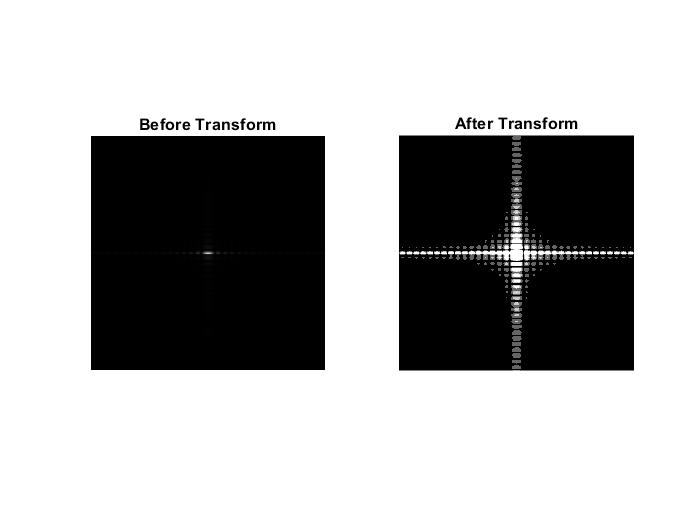


c = 100;    % c values from 0 to 100 with step size of 0.1

image = imread('Fig2_6.tif');
image_double = im2double(image);

image_mod = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_double(i,j);
        image_mod(i,j) = c * (log(1+r));
    end
end

figure();
subplot(1,2,1)
imshow(image_double);
title("Before Transform");
subplot(1,2,2)
imshow(image_mod);
title("After Transform");

Explanation: Logarithmic transform applied to the image with the constant c = 100. This results in a very large logarithmic scale transform of the image and the difference between lights and darks. This illimunates the very small changes between light and dark revealing much for information about the image that was previously unseen.

4.  Test Log transformations $s=c*\mathrm{log}\left(1+r\right)$ and power-law transformations $s=c*r^{\gamma }$ code on the image Fig2_8.tif to get your best enhancement and show your result.

clear

fprintf("Question 4:")

Question 4:

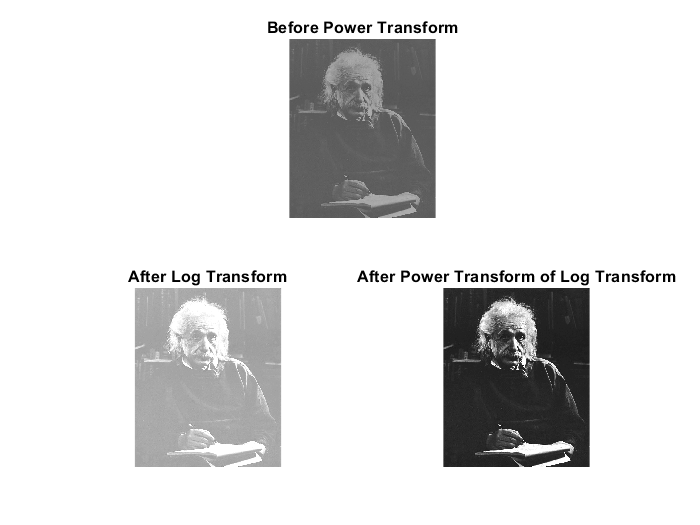


cL = 2.1;  % c log values from 0 to 3 with step size of 0.01
cP = 0.8;    % c power values from 0 to 20 with step size of 0.01
y  = 4;     % gamma values from 0 to 5 with step size of 0.01

image = imread('Fig2_8.tif');
image_double = im2double(image);

image_mod_log = zeros(size(image_double));
image_mod_pow = zeros(size(image_double));

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_double(i,j);
        image_mod_log(i,j) = cL * (log(1+r));
    end
end

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_mod_log(i,j);
        image_mod_pow(i,j) = cP * (r^y);
    end
end

figure();
subplot(2,2,[1 2]);
imshow(image_double);
title("Before Power Transform");
subplot(2,2,4);
imshow(image_mod_pow);
title("After Power Transform of Log Transform");
subplot(2,2,3);
imshow(image_mod_log);
title("After Log Transform");

Explanation: First a logarithmic transform was applied to the image to attempt to eliminate the "grey filter" over the image adjusting the differences between light and dark of the image, extending the lights up in range, and truncating the left over filter. This preps the image to be filtered again by a power-transformation which with the applied constants greatly extends the range of the darks eliminating the washed-out look left by the logartihmic-transform.